# Sistemes Equacuions NO lineals

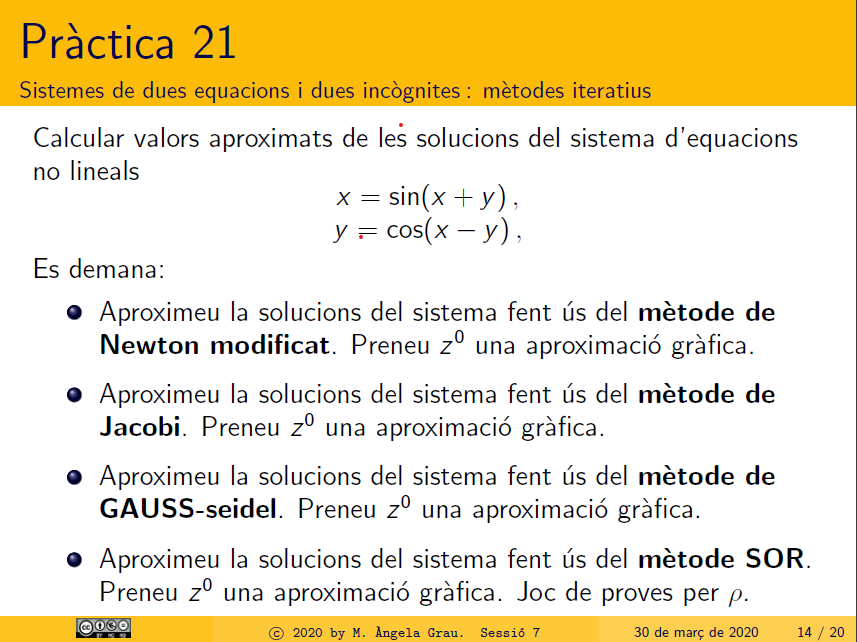

Per obtenir una z0 per aproximació gràfica

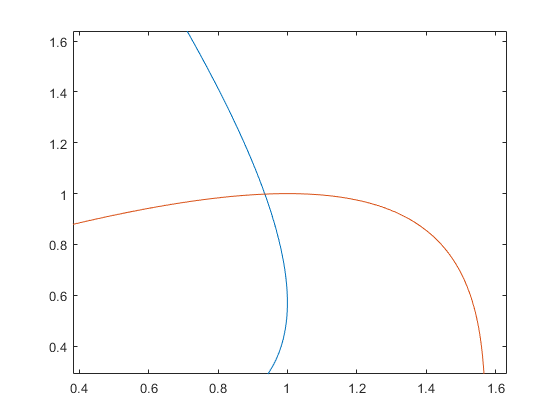

clearvars;

F1=@(x,y)x-sin(x+y);
F2=@(x,y)y-cos(x-y);
fimplicit({F1,F2})

xlim([0.382 1.633])
ylim([0.29 1.64])

% Interval Aproximat
Z0=[0.8;1];

Nmax=50;
tolF= 0.5*10^(-7);
tolZ= 0.5*10^(-7);

F=@(x,y)[x-sin(x+y); y-cos(x-y)];
DF=@(x,y)[1-cos(x+y), -cos(x+y); sin(x-y), 1-sin(x-y)];

% Metode Newton Modificat
alpha = newton2Mod(F,DF,Z0,Nmax,tolF,tolZ)

alpha =     0.9351
    0.9980



% Metode Jacobi
alpha = jacobi2V(F,DF,Z0,Nmax,tolF,tolZ)

alpha =     0.9351
    0.9980



% Metode Gauss-Seidel
alpha = gaussSeidel2(F,DF,Z0,Nmax,tolF,tolZ)

alpha =     0.9351
    0.9980



% Metode SOR

RES=[];
for p= -0.5:0.1:0.5
    elem.p=p;
    elem.alpha= SOR2(F,DF,Z0,p,Nmax,tolF,tolZ);
    RES= [RES elem];
end

RES

RES = 1×11 struct array with fields:
    p
    alpha


## Exercici 3 

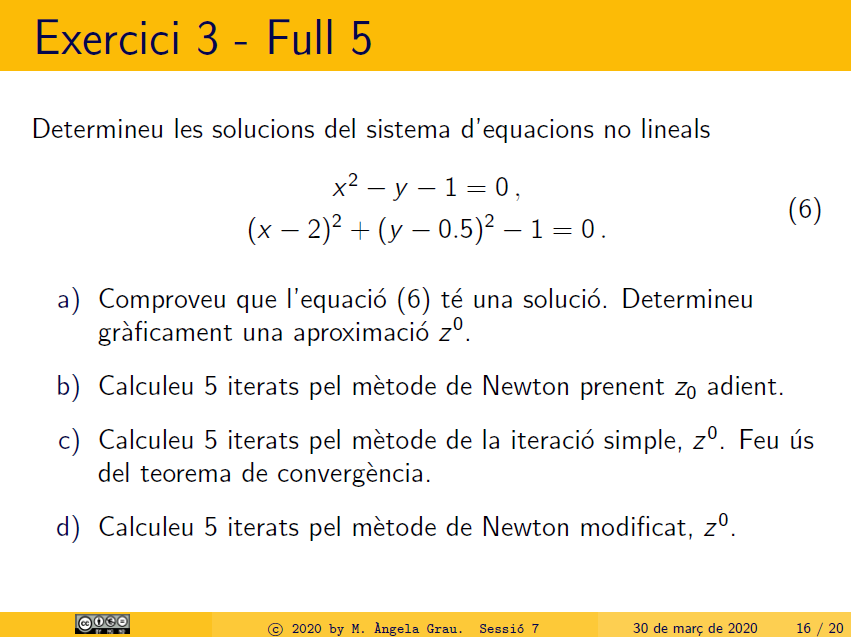

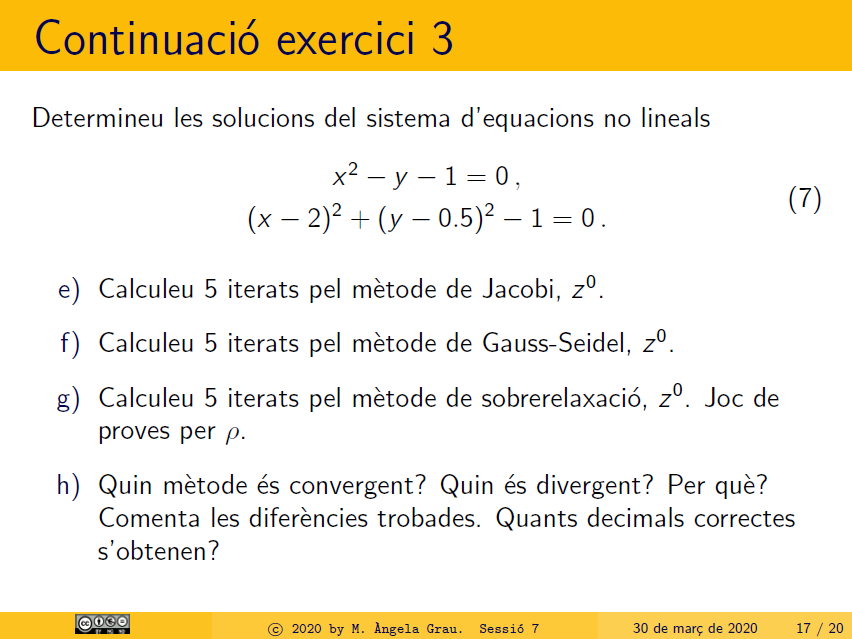

clearvars;

F1=@(x,y)x^2-y-1;
F2=@(x,y)(x-2)^2+(y-0.5)^2-1;

fimplicit({F1,F2})

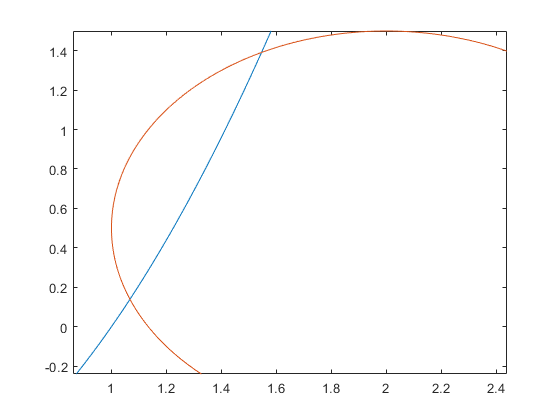


xlim([0.86 2.44])
ylim([-0.24 1.50])

% Interval aproximat

Z0= [1;1.2];

Nmax=5;
tolF= 0.5*10^(-7);
tolZ= 0.5*10^(-7);

F=@(x,y)[x^2-y-1; (x-2)^2+(y-0.5)^2-1];
DF=@(x,y)[2*x,-1; 2*(x-2), 2*(y-0.5)];

% Metode Newton
alpha= newton2d(F,DF,Z0,Nmax,tolF,tolZ)

alpha =     1.5464
    1.3914


El mètode ha estat convergent ja que els nombres són coherents

% Metode iteració simple
syms x y
JG(x,y)=jacobian(F(x,y),[x,y]);
control=JG(Z0(1),Z0(2)); 
control2=norm(control,1); 
criteriTEOREMA=vpa(control2,8);

clear x y G(x,y) JG(x,y)
if criteriTEOREMA >=1 
    disp('Metode divergent')
else
disp('Metode convergent')
alpha = itera2d(F,DF,Z0,Nmax,tolF);
end

Metode divergent


% Metode Newton Modificat
alpha = newton2Mod(F,DF,Z0,Nmax,tolF,tolZ,5)

alpha = 	1.0e+14 *

   -0.5676
   -1.0579


En aquest cas el màtode de newton modificat ens ha sortit una execució divergent, posiblement sigui degut a que no actualitzem la matriu Jacobiana el suficient, ja que en el cas de newton normal ha estat convergent.

% Metode Jacobi
alpha = jacobi2V(F,DF,Z0,Nmax,tolF,tolZ)

alpha =     1.5701
    1.4012


El mètode ha estat convergent ja que els nombres són coherents


% Metode Gauss-Seidel
alpha = gaussSeidel2(F,DF,Z0,Nmax,tolF,tolZ)

alpha =     1.5474
    1.3917


El mètode ha estat convergent ja que els nombres són coherents


% Metode SOR

RES=[];
for p= -0.5:0.1:0.5
    elem.p=p;
    elem.alpha= SOR2(F,DF,Z0,p,Nmax,tolF,tolZ);
    RES= [RES elem];
end

RES

RES = 1×11 struct array with fields:
    p
    alpha


El mètode ha estat convergent ja que els nombres són coherents